**The iLQR on the cart and pole system**

Consider the cart-and-pole system here depicted:

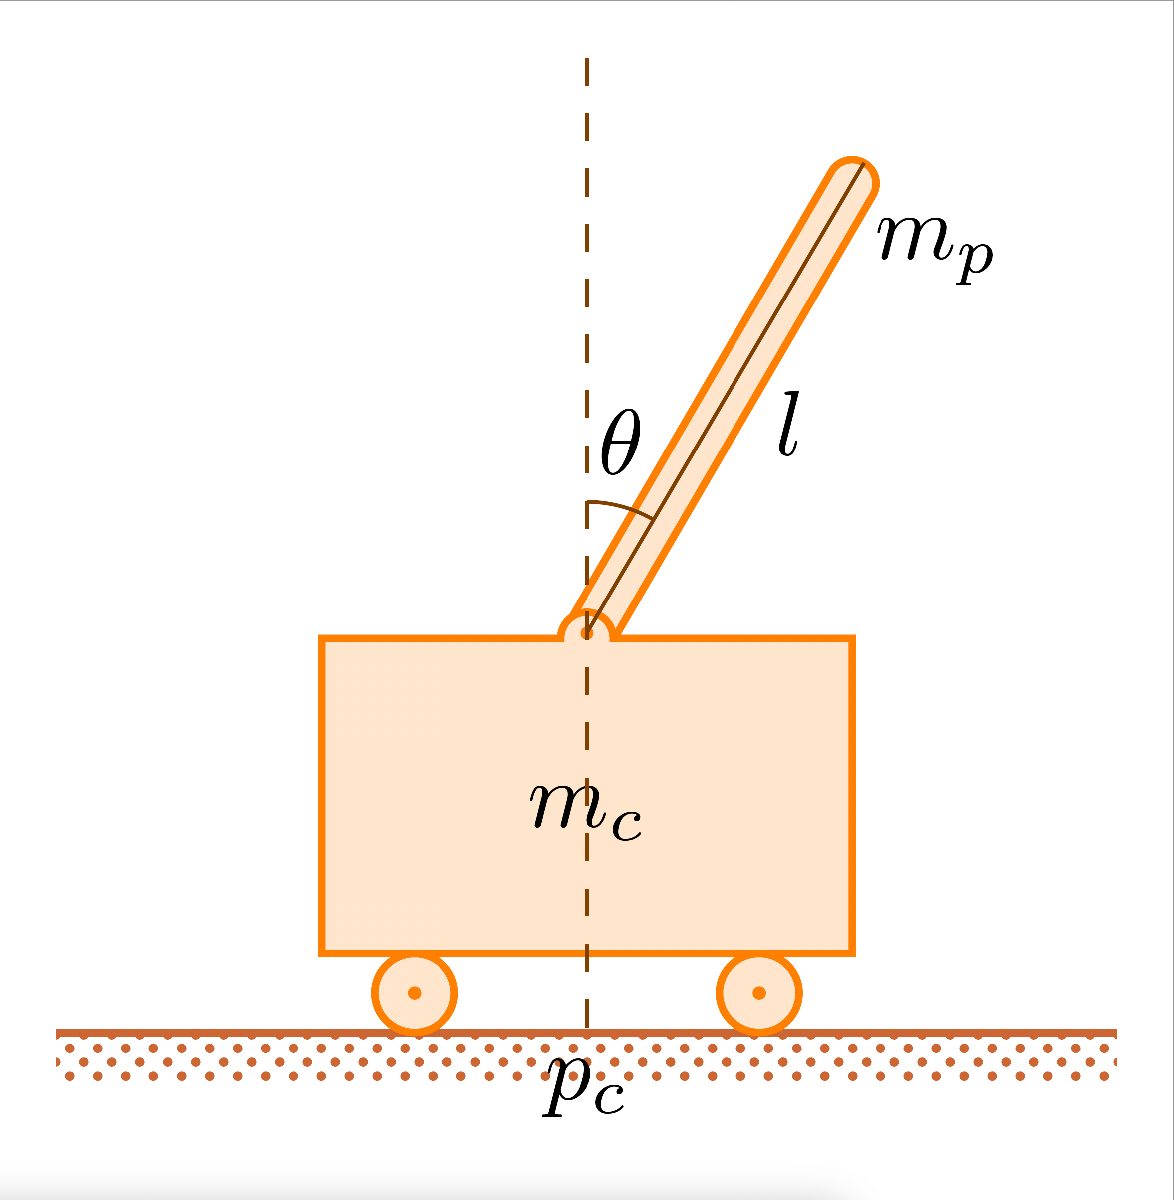

whose dynamics follows the following equations:


$$\ddot{\theta}=\frac{g \sin(\theta)\,+\,\cos(\theta) \left[ \frac{-F\,-\,m_p\,l\,\dot{\theta}^2 \sin \left(\theta\right)\,+\,\mu_c\,\text{sgn}\left(\dot{p}_c\right)}{m_c\,+\,m_p}\right]-\frac{\mu_p\dot{\theta}}{m_p\,l}}{l\,\left[\frac{4}{3}-\frac{m_p\,cos^2\left(\theta\right)}{m_c\,+\,m_p}\right]}$$
   


$$(*)$$



$$  \ddot{p}_c=\frac{F\,+\,m_p\,l\,\left[\dot{\theta}^2\,\sin\left(\theta\right)\,-\,\ddot{\theta}\,\cos(\theta)\right]}{m_c\,+\,m_p}$$


where $g = 9.8\,\text{m/sec}$ is the gravitational acceleration, $m_c = 1\,\text{kg}$ is the cart mass, $m_p = 0.1\,\text{kg}$ is the pole mass, $l = 0.5\,\text{m}$ is the half-pole length, $\mu_p = 0.000002$ is the pole on cart friction coefficient.

- Simulate the non linear cart and pole system applying the provided control input sequence $\bar{u}^{(k)}$ with a sample time of 0.005 sec. Record the resulting state trajectory $\bar{x}^{(k)}$with an initial state of $\theta =180$, $\dot{\theta}=0$, $p_c=0$, $\dot{p}_c=0$. Plot the resulting trajectory.

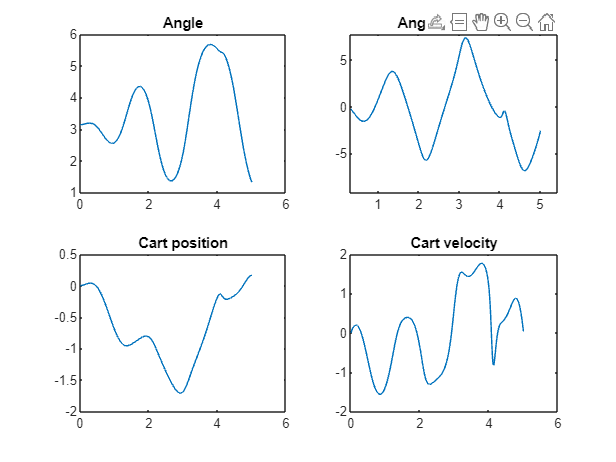

% Provide the code
clear all
close all
clc


% constants definition
g = 9.8; % gravitational acceleration
mc = 1;   % cart mass [kg]
l = 0.5; % half-pole length [m]
mp = 0.1; % pole mass [kg]
mup = 0.000002; % pole friction coefficient

theta0 = 180;
x0 = 0; 
dot_x0 = 0;
dot_theta0 = 0;

t2=0;
conds=[deg2rad(theta0), dot_theta0, x0, dot_x0];
X_nl = conds';

load ilqr_u


U=input_traj;
u = U;
N=length(u);
timestep = 0.005;

for i = 1:N
    t1 = t2;
    t2 = t2+timestep;
    time = [t1, t2];
    [t,state] = ode45(@(t,x)solving1(t, x, g, u(i), mp, l, mc, mup), time, conds);
    tp = find(t == t2);
    conds = state(tp,:);
    X_nl = [X_nl, conds'];
end


tfin = timestep*length(X_nl)-timestep;

figure()
subplot(2,2,1)
plot(0:timestep:tfin,X_nl(1,:))

title('Angle');
subplot(2,2,2)
plot(0:timestep:tfin,X_nl(2,:))

title('Angular velocity');
subplot(2,2,3)
plot(0:timestep:tfin,X_nl(3,:))

title('Cart position');
subplot(2,2,4)

plot(0:timestep:tfin,X_nl(4,:))
title('Cart velocity');

X_bar=X_nl;

 2. Linearize the non-linear cart and pole system around the nominal state-input trajectories $\{\bar{x}^{(k)},\bar{u}^{(k)}\}$previously obtained, and store the time-varying matrices of the linearized system$\{A(k),B(k)\}$

% Provide the code
% Answer: (Provide the code, an animation of the system the plots of the state evolution)
 % cleaning the workspace
sympref('default');
syms theta dt pc dpc
format short
syms u g mc mp l mu_p
load ilqr_u

U=input_traj;
syms f1(theta, dt, pc , dpc) f2(theta, dt, pc , dpc)


f1(theta, dt, pc , dpc)=(((g*sin(theta)+cos(theta)*(((-u-mp*l*(dt^2)*sin(theta))/(mc+mp)))-(mu_p*dt)/(mp*l)))/(l*(4/3-(mp*(cos(theta)^2)/(mc+mp)))));

f2(theta, dt, pc , dpc)=(u+mp*l*(((dt)^2)*sin(theta)-(f1(pc, dpc, theta, dt))*cos(theta)))/(mc+mp);
f_x=jacobian([dt;f1;dpc;f2],[theta;dt;pc;dpc]);
g_x=jacobian([dt;f1;dpc;f2],[u]);

%evaluating A matrix after linearization
A1=eval(f_x);
B1=eval(g_x);
n=size(A1);

g=9.8;
mp=0.1;
mc=1;
mu_p=0.000002;
l=0.5;

%value=[g, mp, mc, mu_p, l];
%A1=subs(A1,value,[9.8 0.1 1 0.000002 0.5]);
%B1=subs(B1,value,[9.8 0.1 1 0.000002 0.5]);
A1=eval(f_x);
B1=eval(g_x);

%TOT={length(X_nl),2};% in Case of using cell
Matrix_A=zeros(4001,4);
Matrix_B=zeros(4001,1);
for i=1:length(U)

theta=X_nl(1,i);
dt=X_nl(2,i);
pc=X_nl(3,i);
dpc=X_nl(4,i);
u=U(i);
A1=eval(f_x);
B1=eval(g_x);
sys=ss(double(A1),double(B1),eye(n),0);
sysTD=c2d(sys, 0.005);
A=sysTD.A;
B=sysTD.B;
Matrix_A((i-1)*4+1:i*4,:)=A;
Matrix_B((i-1)*4+1:i*4,:)=B;
%TOT{i,1}=A; %In case of using cell, not so efficient method
%TOT{i,2}=B;

end


        3. Compute the discrete-time homogeneous representation of the linear time-varying cart and pole system obtained at point 2 and store the matrices of the homogeneous representation

% Provide the code


%TOT_cap={length(X_nl),2};
Matrix_capA=zeros(5005,5);
Matrix_capB=zeros(5005,1);
for i=1:length(U)
Aom=Matrix_A((i-1)*4+1:i*4,:);
Bom=Matrix_B((i-1)*4+1:i*4,:);
A_cap=[Aom ,zeros(4,1);
       zeros(1,4),  1];
B_cap=[Bom;0];

Matrix_capA((i-1)*5+1:i*5,:)=A_cap;
Matrix_capB((i-1)*5+1:i*5,:)=B_cap;
%TOT_cap{i,1}=A_cap;
%TOT_cap{i,2}=B_cap;
end




      4. Assume $Q=I$ and $R=1$, the cost matrices for a swing up cart and pole task, and compute $\hat{Q}(k)=$$\left\lbrack \begin{array}{cc}
Q & -{q^{\left(k\right)} }^{\top } \\
{-q}^{\left(k\right)}  & d^{\left(k\right)} 
\end{array}\right\rbrack$where $$\bar{x}^{{(k)}^\top} Q \bar{x}^{(k)}=d^{(k)}$$ and $$2\bar{x}^{{(k)}^\top} Q=2 q^{{(k)}^\top}$$for the entire nominal state trajectory  and store them

% Provide the code
%Q_TOT={length(X_nl),1};
Q_TOT=zeros(5005,5);
for i=1:length(U)
Q=eye(4);
q_k_trasp=X_nl(:,i)'*Q;
d=X_nl(:,i)'*Q*X_nl(:,i);
Q_cap=[Q -q_k_trasp';
       -q_k_trasp d];
Q_TOT((i-1)*5+1:i*5,:)=Q_cap;
end

      5. Solve the finite-horizon LQR problem on the linearized version of the system and store the control gain matrices $\{K(k)\}$. Assume that $P_H =\left\lbrack \begin{array}{cc}
I & 0\\
0 & 0
\end{array}\right\rbrack$.

% Provide the code
%VERIFICARE CHE QK sia semidefinita positiva per ogni k e applicare riccati
%recursion, backwards forward , Ph qua è l'ultima , partire da istante
%ultimo
epsilon = 1e-14

epsilon = 1.0000e-14

for i=1:1:length(U)
d = eig(Q_TOT((i-1)*5+1:i*5,:));
d(1);
isposdef = all(d >= -epsilon) && all(abs(d) > epsilon);

if isposdef==1   disp('Oh no there is one not positive semidefinite ')
    disp(i);


end
end

R=1;
P_H=[1, 1, 1, 1, 0;
     1, 1, 1, 1, 0;
     1, 1, 1, 1, 0;
     1, 1, 1, 1, 0;
     0, 0, 0, 0, 0;
     ];
K_TOT=zeros(5005,1);

%for i=1:1length(TOT)
P=P_H;
i=1;
A=Matrix_capA((5005-i*5+1) : (5005-(i-1)*5),:);
B=Matrix_capB((5005-i*5+1) : (5005-(i-1)*5),:);
K=(R+B'*P*B)*B'*P*A;
K_TOT((5005-5+1) : 5005,:)=K;
for i=2:1:length(U)


A=Matrix_capA((5005-i*5+1) : (5005-(i-1)*5),:);
B=Matrix_capB((5005-i*5+1) : (5005-(i-1)*5),:);

Q=Q_TOT((5005-i*5+1) : (5005-(i-1)*5),:);
P=riccati(A,B,Q,R,P);

K=(R+B'*P*B)*B'*P*A;
K_TOT((5005-i*5+1) : (5005-(i-1)*5),:)=K;

end


%{

P=riccati(A,B,Q,R,P);
 P = struct2array(P);
 P=[double(P(1:5));
    double(P(6:10));
    double(P(11:15));
    double(P(16:20));
    double(P(21:25))];
K=(R+B'*P_H*B)*B'*P*A_cap;
K_TOT{1001-i,1}=K;
end
%}

  6. Simulate the non-linear cart and pole system applying the computed control gain matrices $\{K(k)\}$ with a sample time of 0.005 sec. Record the resulting <state and control input trajectory $\{\bar{x}^{(k)},\bar{u}^{(k)}\}$with an initial state of $\theta =180$, $\dot{\theta}=0$, $p_c=0$, $\dot{p}_c=0$. Plot the resulting trajectories

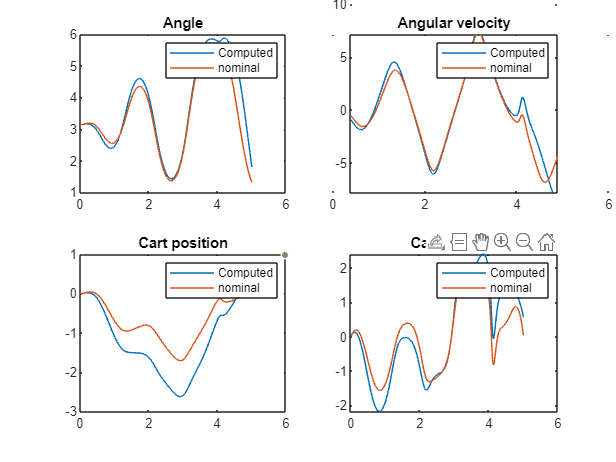

% constants definition
g = 9.8; % gravitational acceleration
mc = 1;   % cart mass [kg]
l = 0.5; % half-pole length [m]
mp = 0.1; % pole mass [kg]
mup = 0.000002; % pole friction coefficient

theta0 = 180;
x0 = 0; 
dot_x0 = 0;
dot_theta0 = 0;

t2=0;
conds=[deg2rad(theta0), dot_theta0, x0, dot_x0];
X_nl = conds';

 X_nl=[X_nl; 1];

u = U;
N=length(u);
timestep = 0.005;

for i = 1:N
    t1 = t2;
    t2 = t2+timestep;
    time = [t1, t2];

    u(i)=-K_TOT((i-1)*5+1:i*5,:)'*([X_nl(1:4,i)-X_bar(:,i);1])+input_traj(i);
    [t,state] = ode45(@(t,x)solving1(t, x, g, u(i), mp, l, mc, mup), time, conds(1:4));
    tp = find(t == t2);
    conds = state(tp,:);
      conds =[conds, 1];
    X_nl = [X_nl, conds'];
end


tfin = timestep*length(X_nl)-timestep;

figure();
subplot(2,2,1);
plot(0:timestep:tfin,X_nl(1,:));
hold on
plot(0:timestep:tfin,X_bar(1,:));

title('Angle');
legend('Computed','nominal');
subplot(2,2,2);
plot(0:timestep:tfin,X_nl(2,:));
hold on
plot(0:timestep:tfin,X_bar(2,:));

title('Angular velocity');
legend('Computed','nominal');
subplot(2,2,3);
plot(0:timestep:tfin,X_nl(3,:));
hold on
plot(0:timestep:tfin,X_bar(3,:));

title('Cart position');
legend('Computed','nominal');
subplot(2,2,4)

plot(0:timestep:tfin,X_nl(4,:));
hold on
plot(0:timestep:tfin,X_bar(4,:));
title('Cart velocity');
legend('Computed','nominal');